# 1. How finite should it be

#### 1.1 Like a hot knive through a Butterworth

pb = [0.2 0.3];
sb = [0.1 0.4];
rp = 2;
Gs = 100;

[n,wn] = cheb1ord(pb,sb,rp,Gs);

[b,a] = cheby1(n,rp,pb,"bandpass");

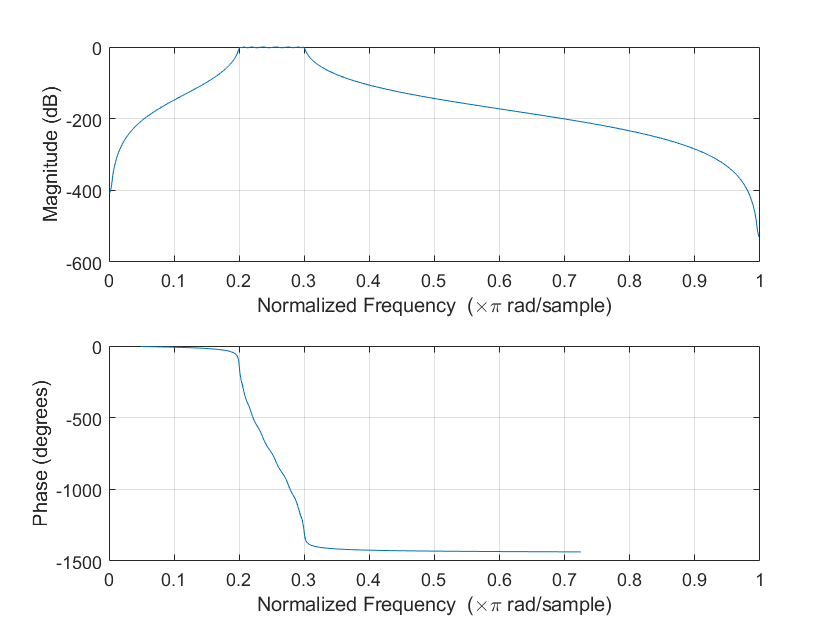

freqz(b,a)

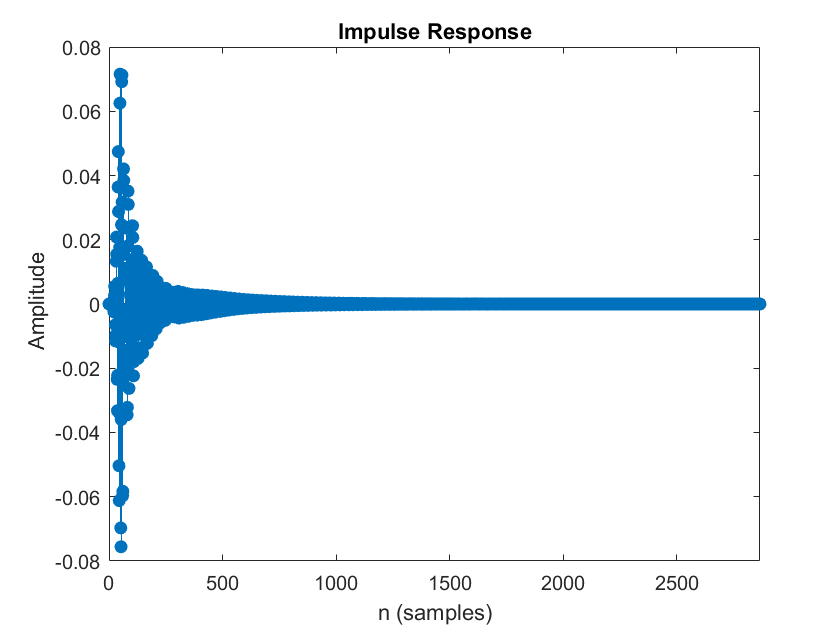

impz(b,a)

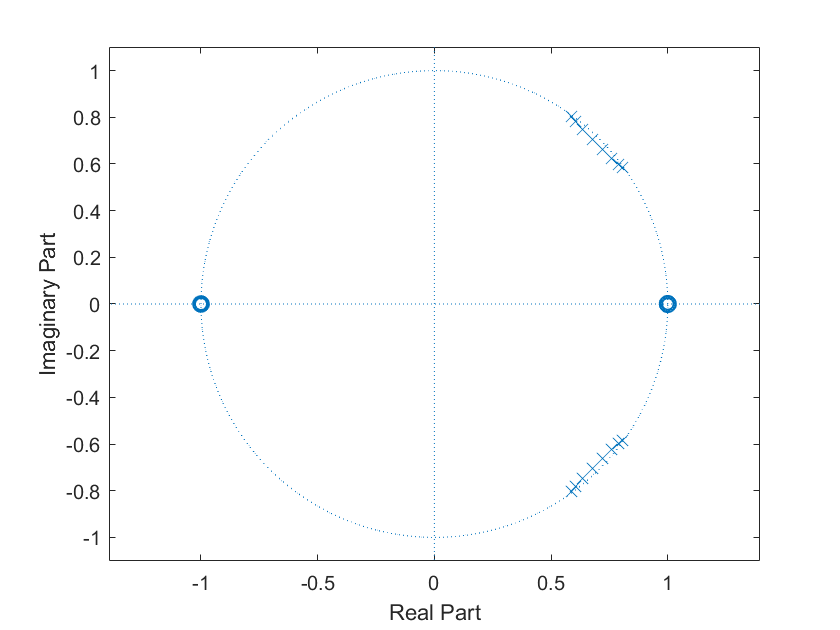

zplane(b,a)

[h,t]  = impz(b,a);
el = find(h > (max(h) * 0.1), 1, 'last')

el = 194

h_ef = h(1:el);
h_75 = h(1:fix(0.75*el));
h_60 = h(1:fix(0.6*el));
h_40 = h(1:fix(0.4*el));
h_10 = h(1:fix(0.1*el));

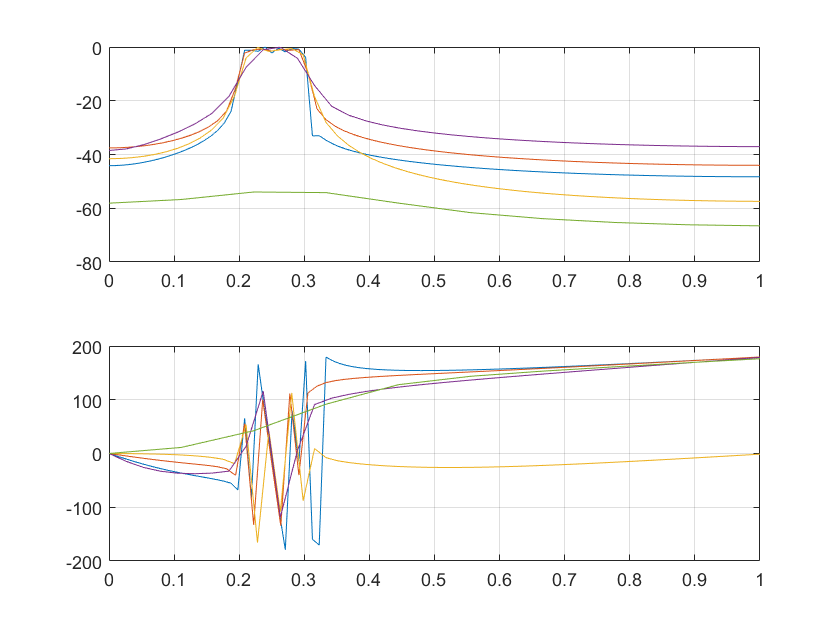

[ef.w,ef.a,ef.p] = makeNormSpec(h_ef);
[e75.w,e75.a,e75.p] = makeNormSpec(h_75);
[e60.w,e60.a,e60.p] = makeNormSpec(h_60);
[e40.w,e40.a,e40.p] = makeNormSpec(h_40);
[e10.w,e10.a,e10.p] = makeNormSpec(h_10);

figure(); subplot(2,1,1); plot(ef.w,ef.a); grid on; hold on; plot(e75.w,e75.a); plot(e60.w,e60.a); plot(e40.w,e40.a); plot(e10.w,e10.a); hold off;
subplot(2,1,2); plot(ef.w,ef.p); grid on; hold on; plot(e75.w,e75.p); plot(e60.w,e60.p); plot(e40.w,e40.p); plot(e10.w,e10.p); hold off;

#### 1.2 Shorter and shorter


$$f_s = 30\;\text{kHz}$$


fs = 30e3;
T = 601/fs

T = 0.0200

delta_f = 1/T

delta_f = 49.9168

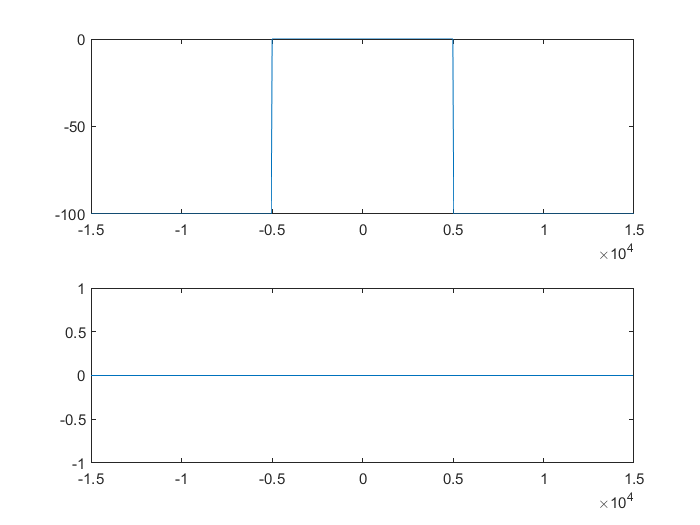

f = 0:delta_f:(fs/2);
Y = 0.00001*ones(1,length(f));
for i = 1:ceil(length(f)/3)
    Y(i) = 1;
end
f = [-flip(f) f(2:end)];
Y = [flip(Y) Y(2:end)];
figure();
subplot(2,1,1); plot(f,20*log10(abs(Y)));
subplot(2,1,2); plot(f,angle(Y)*180/pi);

h = ifft(ifftshift(Y));
t = 0:(1/fs):(T-1/fs);
length(t)

ans = 601

length(h)

ans = 601

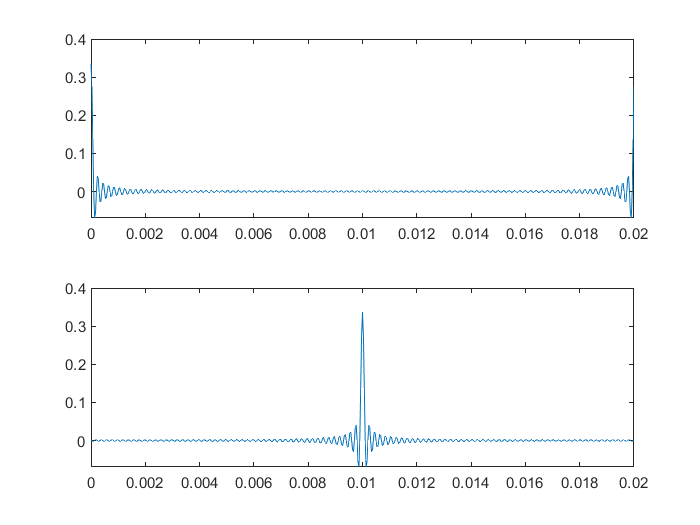

figure(); subplot(2,1,1); plot(t,h);
subplot(2,1,2); plot(t,fftshift(h))

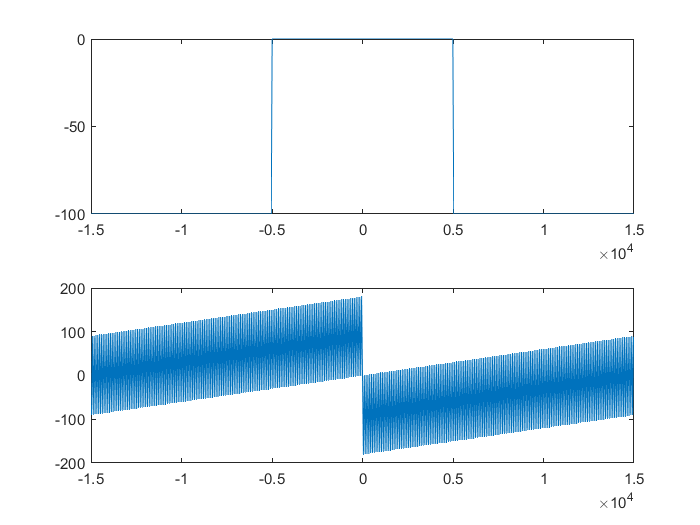

Y2 = fftshift(fft(fftshift(h)));
figure();
subplot(2,1,1); plot(f,20*log10(abs(Y2)));
subplot(2,1,2); plot(f,angle(Y2)*180/pi);

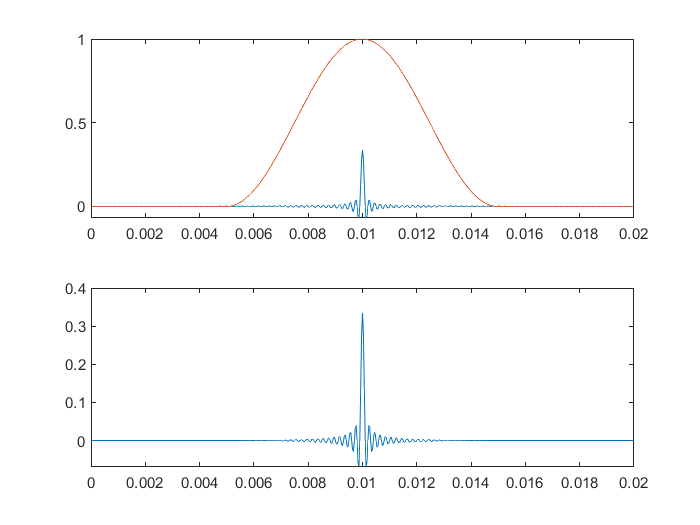


w = [zeros(1,0.005*fs) hann(0.01*fs)' zeros(1,0.005*fs+1)];
w_sig = w.*fftshift(h);
figure(); subplot(2,1,1); plot(t,fftshift(h)); hold on; plot(t,w);  hold off; subplot(2,1,2); plot(t,w_sig);

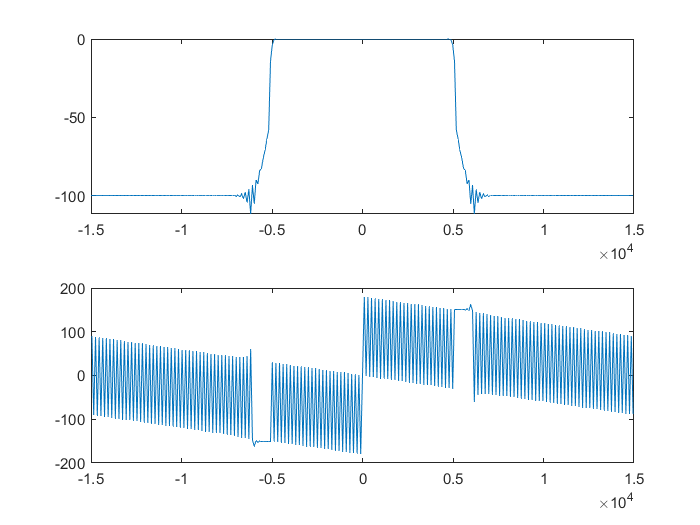

Y3 = fftshift(fft(w_sig(0.005*fs:0.015*fs)));
T = length(Y3)/fs;
delta_f = 1/T;
f = 0:delta_f:(fs/2);
f = [-flip(f) f(2:end)];
figure();
subplot(2,1,1); plot(f,20*log10(abs(Y3)));
subplot(2,1,2); plot(f,angle(Y3)*180/pi);

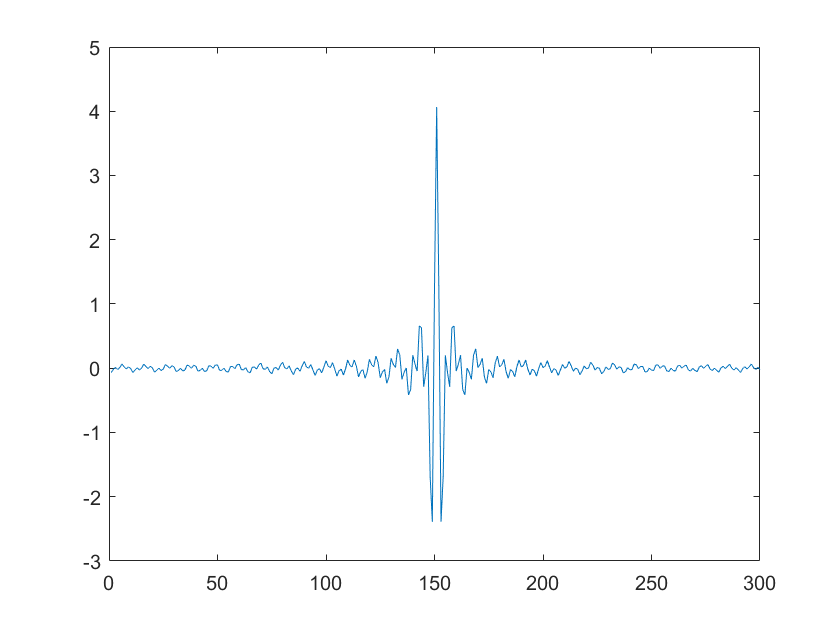

wc_lwr = 0.2;
wc_upr = 0.6;
G = 20;
L = 300;
idx_lwr = fix(wc_lwr*(L/2));
idx_upr = fix(wc_upr*(L/2));
Y = 0.000000001*ones(1,(L/2)+1);
for i = idx_lwr:idx_upr
    Y(i) = 10^(G/20);
end
Y = [flip(Y) Y(2:end-1)];
h = ifft(ifftshift(Y));
figure();plot(fftshift(h))

h = fftshift(h);

cutfrac = 0.5;

w = hamming(ceil(L*(1-cutfrac)))'

w =     0.0800    0.0804    0.0816    0.0837    0.0865    0.0902    0.0946    0.0999    0.1059    0.1127    0.1203    0.1286    0.1376    0.1474    0.1579    0.1690    0.1808    0.1932    0.2063    0.2199    0.2341    0.2489    0.2642    0.2799    0.2961    0.3128    0.3299    0.3473    0.3651    0.3832    0.4015    0.4202    0.4390    0.4580    0.4772    0.4964    0.5158    0.5352    0.5545    0.5739    0.5932    0.6124    0.6315    0.6504    0.6692    0.6877    0.7059    0.7238    0.7415    0.7587


w_sig = w.*h(fix(cutfrac*1/2*L):fix(cutfrac*1/2*L+(1-cutfrac)*L)-1)

w_sig =    -0.0070   -0.0000    0.0011   -0.0024    0.0041    0.0085    0.0007   -0.0009    0.0039   -0.0048   -0.0121   -0.0018    0.0005   -0.0069    0.0057    0.0180    0.0037    0.0002    0.0121   -0.0062   -0.0263   -0.0067   -0.0015   -0.0203    0.0054    0.0369    0.0110    0.0035    0.0322   -0.0022   -0.0495   -0.0165   -0.0063   -0.0488   -0.0047    0.0639    0.0230    0.0094    0.0712    0.0168   -0.0795   -0.0303   -0.0126   -0.1010   -0.0365    0.0962    0.0381    0.0149    0.1403    0.0667


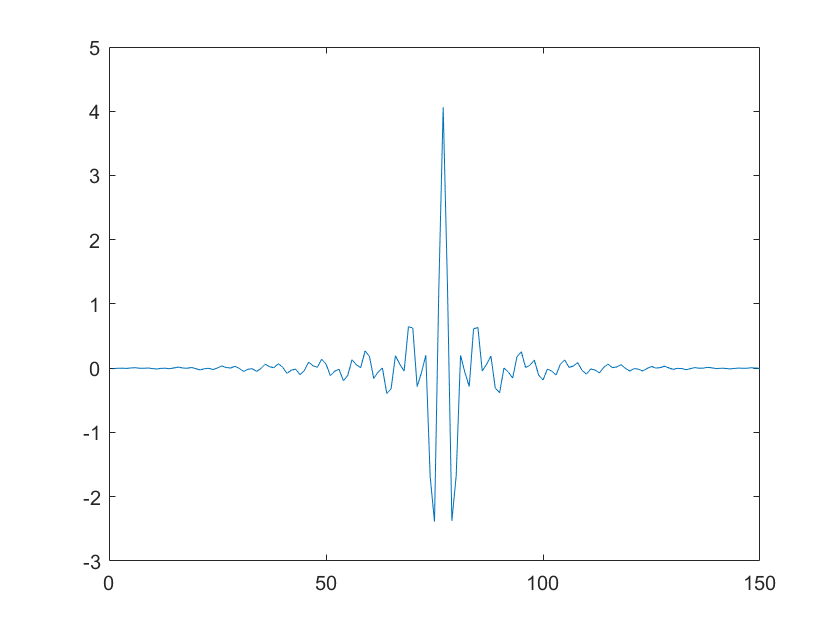

figure();plot(w_sig)

b=w_sig

b =    -0.0070   -0.0000    0.0011   -0.0024    0.0041    0.0085    0.0007   -0.0009    0.0039   -0.0048   -0.0121   -0.0018    0.0005   -0.0069    0.0057    0.0180    0.0037    0.0002    0.0121   -0.0062   -0.0263   -0.0067   -0.0015   -0.0203    0.0054    0.0369    0.0110    0.0035    0.0322   -0.0022   -0.0495   -0.0165   -0.0063   -0.0488   -0.0047    0.0639    0.0230    0.0094    0.0712    0.0168   -0.0795   -0.0303   -0.0126   -0.1010   -0.0365    0.0962    0.0381    0.0149    0.1403    0.0667


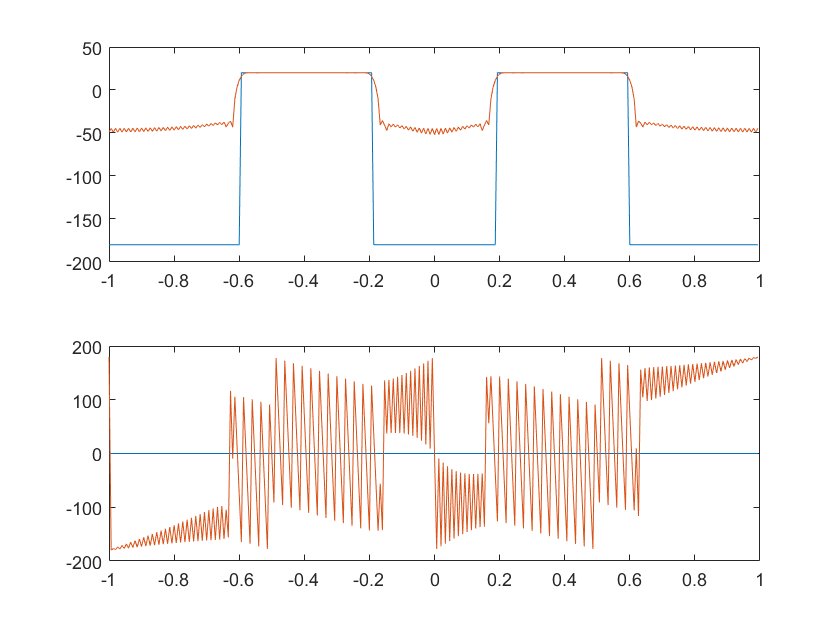

a=[1];
[h,w] = freqz(b,a,300,'whole');
h = fftshift(h);
f = 0:1/150:1;
f = [-flip(f) f(2:end-1)];

figure();subplot(2,1,1);plot(f,20*log10(abs(Y)));hold on;plot(f,20*log10(abs(h))); hold off; subplot(2,1,2); plot(f,angle(Y)*180/pi); hold on;plot(f,angle(h)*180/pi); hold off;

# 2. An equalizer - without buttons

#### 2.1 Bass and treble

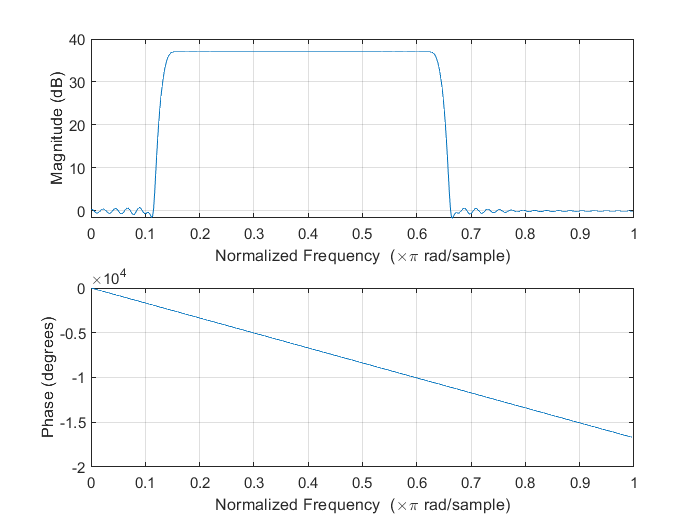

[b,a] = FirBandpass(... 
0.1445,...
0.6436, ...
  37, ...
  370);

freqz(b,a)

[s,fs] = audioread("hum.wav")

s =     0.6419
    0.6427
    0.6439
    0.6466
    0.6465
    0.6470
    0.6444
    0.6465
    0.6464
    0.6419


fs = 22050

sound(filter(b,a,s((10*fs):(20*fs))),fs)

function [b,a] = FirBandpass(wc_lwr,wc_upr,G,L)
    idx_lwr = fix(wc_lwr*(L/2));
    idx_upr = fix(wc_upr*(L/2));
    Y = ones(1,ceil((L/2)));
    for i = idx_lwr:idx_upr
        Y(i) = 10^(G/20);
    end
    if mod(L,2) == 0
        Y = [flip(Y) Y(2:end-1)];
    else
        Y = [flip(Y) Y(2:end)];
    end
    
    h = fftshift(ifft(ifftshift(Y)));

    cutfrac = 0.5; % how much percent of the IR should be discarded
    
    w = hamming(fix(L*(1-cutfrac)))';
    if mod(L,2) == 0
        sub_h = h(fix(cutfrac*1/2*L):fix(cutfrac*1/2*L)+fix((1-cutfrac)*L)-1);
    else
        sub_h = h(fix(cutfrac*1/2*L):fix(cutfrac*1/2*L)+fix((1-cutfrac)*L)-1);
    end
    w_sig = w.*sub_h;
    b=w_sig;
    a=1;
end
function [w,amp,phase] = makeNormSpec(h)
    y = fft(h);
    y = y(1:ceil(length(y)/2));
    w = linspace(0,1,length(y));
    amp = 20*log10(abs(y));
    phase = angle(y)*180/pi;
end